# File input and output

## High level file IO

Variables from the workspace can be saved as a binary MAT-file with the `save` command.

clearvars
A = hilb(3);
B = magic(3);
save AB.mat A B

We can check which variables a MAT-file has with the `whos`-command.

whos -file AB.mat

  Name      Size            Bytes  Class     Attributes

  A         3x3                72  double              
  B         3x3                72  double              



We can also append variables to an existing MAT-file.

C1 = rand(2); C2 = randn(3); C3 = randi(100, 5);
save AB.mat C1 C2 C3 -append
whos -file AB.mat

  Name      Size            Bytes  Class     Attributes

  A         3x3                72  double              
  B         3x3                72  double              
  C1        2x2                32  double              
  C2        3x3                72  double              
  C3        5x5               200  double              



The `load` command is used to read variables from a MAT-file. This reads the variables into the structure array `S`. The results are identical to the original matrices.

S = load('AB.mat')

S = struct with fields:
     A: [3×3 double]
     B: [3×3 double]
    C1: [2×2 double]
    C2: [3×3 double]
    C3: [5×5 double]


[isequal(A, S.A) isequal(B, S.B) isequal(C1, S.C1) isequal(C2, S.C2),...
    isequal(C3, S.C3)]

ans = 1×5 logical array
   1   1   1   1   1


We can only load some of the variables and also use regular expressions.

S1 = load('AB.mat', 'A', 'B')

S1 = struct with fields:
    A: [3×3 double]
    B: [3×3 double]


S2 = load('AB.mat', '-regexp', 'C*')

S2 = struct with fields:
    C1: [2×2 double]
    C2: [3×3 double]
    C3: [5×5 double]


Variables can also be saved in ASCII form. Notice that the variables are stored as a single rectangular array, so we lose information on which variable has which value.

save AB.txt A B -ascii
type AB.txt


   1.0000000e+00   5.0000000e-01   3.3333333e-01
   5.0000000e-01   3.3333333e-01   2.5000000e-01
   3.3333333e-01   2.5000000e-01   2.0000000e-01
   8.0000000e+00   1.0000000e+00   6.0000000e+00
   3.0000000e+00   5.0000000e+00   7.0000000e+00
   4.0000000e+00   9.0000000e+00   2.0000000e+00


The default precision is 8 digits, so saving the variables in ASCII form usually loses information.

AB = load('AB.txt',  '-ascii')

AB =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000
    8.0000    1.0000    6.0000
    3.0000    5.0000    7.0000
    4.0000    9.0000    2.0000


A - AB(1:3, :)

ans =    1.0e-08 *

         0         0    0.3333
         0    0.3333         0
    0.3333         0         0


B - AB(4:6, :)

ans =      0     0     0
     0     0     0
     0     0     0


The command `dlmwrite` writes a file that spreadsheet programs can read.

dlmwrite('Test.csv', A)
type Test.csv


1,0.5,0.33333
0.5,0.33333,0.25
0.33333,0.25,0.2


dlmwrite('Test.csv', B, '-append')
type Test.csv


1,0.5,0.33333
0.5,0.33333,0.25
0.33333,0.25,0.2
8,1,6
3,5,7
4,9,2


We can set the delimiter and precision.

dlmwrite('Test1.csv', C2, 'delimiter', ';', 'precision', 16)
type Test1.csv


2.109338402094177;1.951378777331152;1.621628471054809
-0.1895254199942562;-0.0742930178005357;-1.106772600683035
-1.003133940456367;-0.5083158894938332;-0.4601269938404373


The command `dlmread` reads ASCII-delimited file of numeric data into matrix. The default delimiter is comma.

M = dlmread('Test.csv')

M =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000
    8.0000    1.0000    6.0000
    3.0000    5.0000    7.0000
    4.0000    9.0000    2.0000


We can read only a specified range given by [R1 C1 R2 C2] where (R1,C1) is the upper left corner and (R2,C2) is the lower right corner. The numbering starts from zero.

M1 = dlmread('Test.csv', ',', [3 1 5 2])

M1 =      1     6
     5     7
     9     2


The range can also be given using spreadsheet notation. This reads the same range as the previous command.

M2 = dlmread('Test.csv', ',', 'B4..C6')

M2 =      1     6
     5     7
     9     2


## The standard file open and save dialogs

The command `uigetfile` opens the system dependent standard open file dialog box. Typical usage example follows. We use the `fullfile` command to combine the filename and pathname components to a full filename. The first argument of `uigetfile` is a filter that determines the initial list of files to show. The second argument is a title of the dialog box.

`[filen, pathn] = uigetfile('*.txt', 'Choose a text file');`

`assert(ischar(filen), 'No file selected.');`

`filename = fullfile(pathn, filen);`

The command `uiputfile` opens the system dependent standard save file dialog box. The arguments are the same as in `uigetfile`. The third argument of `uiputfile` is the initial file name, which the user can change.

`[filen, pathn] = uiputfile('', 'Save the file as', 'foo.txt');`

`assert(ischar(filen), 'No file selected.');`

`filename = fullfile(pathn, filen);`

## Low level file IO

We can also read and write data at the byte or character level with the low level file operations. With the low level file operations we must first open the file with `fopen` and close it when we are done with `fclose`. The basic template is as follows. Here `fid` is a file descriptor to be used in the read and write commands. If the file cannot be opened, `fid = -1`, and `message` is a system dependent error message.

`[fid, message] = fopen('filename', ...)`

`assert(fid >= 0, message)`

`% do some stuff`

`fclose(fid)`

Here we read the matrices from the file AB.txt. The format specifier '%f' means floating point numbers, the argument [3, 6] reads 3 columns by 6 rows. This produces a transposed result, so we take transpose of D at the end.

fid = fopen('AB.txt', 'r')

fid = 3

D = fscanf(fid, '%f', [3 6])

D =     1.0000    0.5000    0.3333    8.0000    3.0000    4.0000
    0.5000    0.3333    0.2500    1.0000    5.0000    9.0000
    0.3333    0.2500    0.2000    6.0000    7.0000    2.0000


fclose(fid);
D'

ans =     1.0000    0.5000    0.3333
    0.5000    0.3333    0.2500
    0.3333    0.2500    0.2000
    8.0000    1.0000    6.0000
    3.0000    5.0000    7.0000
    4.0000    9.0000    2.0000


Next we print the matrix B from above to the file B.txt with the rows prefixed with the strings Row1, Row2 and Row3.

fid = fopen('B.txt', 'w')

fid = 3

for k = 1:3
    s = ['Row', num2str(k)];
    fprintf(fid, '%s ', s);
    fprintf(fid, '%.6f ', B(k, :));
    fprintf(fid, '\n');
end
fclose(fid);
type B.txt


Row1 8.000000 1.000000 6.000000 
Row2 3.000000 5.000000 7.000000 
Row3 4.000000 9.000000 2.000000 


The command textscan reads formatted data from a file into a cellarray. Let us read the file B.txt.

fid = fopen('B.txt', 'r')

fid = 3

C = textscan(fid, '%s%f%f%f')

C = 1×4 cell array
    {3×1 cell}    {3×1 double}    {3×1 double}    {3×1 double}


fclose(fid);

Notice that the fields are read columnwise.

C{1}

ans = 3×1 cell array
    {'Row1'}
    {'Row2'}
    {'Row3'}


C{2}

ans =      8
     3
     4


C{3}

ans =      1
     5
     9


C{4}

ans =      6
     7
     2


## Reading and writing video files

Video files can be read with the `VideoReader` object.

xylo = VideoReader('xylophone.mp4');
get(xylo)

obj =   VideoReader with properties:

   General Properties:
            Name: 'xylophone.mp4'
            Path: '/Applications/MATLAB_R2017b.app/toolbox/matlab/audiovideo'
        Duration: 4.7000
     CurrentTime: 0
             Tag: ''
        UserData: []

   Video Properties:
           Width: 320
          Height: 240
       FrameRate: 30
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


To play the video we first allocate memory for the movie structure.

xylomov = struct('cdata', zeros(xylo.Height, xylo.Width, 3, 'uint8'),...
    'colormap', []);

Next we read the video frames into the movie structure.

k = 1;
while hasFrame(xylo)
    xylomov(k).cdata = readFrame(xylo);
    k = k + 1;
end

Now we play the movie with the video's frame rate. First make a figure of the right size.

h = figure('visible','on')

h =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 678 560 420]
       Units: 'pixels'

  Show all properties


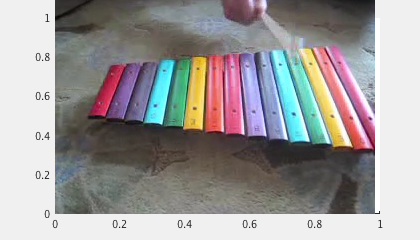

set(h, 'Position',[200 200 xylo.Width+100 xylo.Height])
movie(xylomov, 1, xylo.FrameRate)

As an example of how to make a video file we make an animation of the unit balls $\|(x, y)\|_p = 1$ in $R^2$ as $p$ varies. Here the $p$-norm of a vector is defined by


$$\|(x, y)\|_p = (|x|^p + |y|^p)^{1/p}$$


First we create a VideoWriter object

pobj = VideoWriter('pnorm', 'mpeg-4')

pobj =   VideoWriter

    General Properties:

       Filename:                 'pnorm.mp4'
       Path:                     '/Users/timoh/Documents/TeX Docs/SC/Material for Exercises'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


open(pobj)

Next we form a grid for computing the function values `Z`. Notice that the 4th argument of `contour` is the vector `[1 1]`, since we want to plot only the contour level with `Z = 1`.

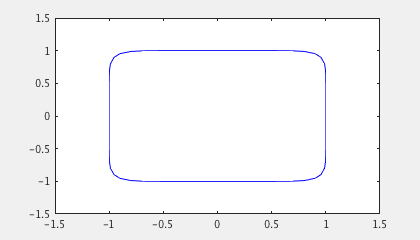

[X, Y] = meshgrid(-1.5:0.1:1.5);
for p = 1:0.01:10
    Z = (abs(X).^p + abs(Y).^p).^(1/p);
    contour(X, Y, Z, [1 1], 'Color', 'b');
    frame = getframe;
    writeVideo(pobj, frame);
end

close(pobj)